% COnstant
% P = 0.95
tp = 2.26;
kp = 1.96;
C = sqrt(3);
delta_M = 0.002;
delta_f = 50;
Cf = sqrt(3);

t_start = 25.0;
t_end = 25.2;
t = mean([t_start, t_end]);
ps = 3169.0;
H = mean([0.39, 0.38]);
pw = H * ps;

% function
fv = @(t, p, pw, vo) vo*sqrt((1 + t/273.15)*(1+0.3192*pw/p))

fv = function_handle with value:
    @(t,p,pw,vo)vo*sqrt((1+t/273.15)*(1+0.3192*pw/p))


% Data here

% f
fi = [37.215 37.211 37.200 37.183 37.186];

% 干涉法
x_gs = [5.210 5.648 6.144 6.600 7.098 7.562 8.010 8.500 8.948 9.416 9.836 10.220];

% 相位比较法
x_xw = [5.182 5.646 6.118 6.580 7.042 7.522 7.980 8.440 8.908 9.366 9.824 10.226];

% Water
x_wt = [2.114 4.690 6.864 9.012 11.106 13.048 14.676 16.412 19.082 21.352];

% 时差法
l_A = [20.856 24.700] .* 10^-2;
t_A = [105 89] .* 10^-6;

l_B = [21.864 17.900] .* 10^-2;
t_B = [153 174] .* 10^-6;

f = mean(fi) * 10^3

f =        37199


% A.1
deltaX = diff(x_gs)

deltaX =                      0.438                     0.496                     0.456                     0.498                     0.464                     0.448                      0.49                     0.448                     0.468                      0.42                     0.384


dx_avg = mean(deltaX)

dx_avg =          0.455454545454546


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:12)';
fun = fit(xx, x_gs', ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4619  (0.4548, 0.469)
       p2 =       4.764  (4.711, 4.816)

lamda = 2 * fun.p1

lamda =          0.923776223776224


v_a = f * lamda * 10^-2

v_a =           343.635517482518



sa = std(deltaX)

sa =         0.0341419496700574


ua = sa / sqrt(12-1)

ua =         0.0102941851515253


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =         0.0233746822797753


U_Lamda = 2 * Ux

U_Lamda =         0.0467493645595507



fa = std(fi)

fa =         0.0143701078632007


f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           7.18505393160033


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           58.8643625917529



U = v_a*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =           17.3987956613031


va = fv(t, ps, pw, v_a)

va =           380.501753845227


% A.2
x_xw = x_xw';
deltaX = diff(x_xw)

deltaX =                      0.464
                     0.472
                     0.462
                     0.462
                      0.48
                     0.458
         0.459999999999999
                     0.468
                     0.458
                     0.458


dx_avg = mean(deltaX)

dx_avg =          0.458545454545455


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:12)';
fun = fit(xx, x_xw, ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4619  (0.4582, 0.4657)
       p2 =       4.734  (4.706, 4.761)

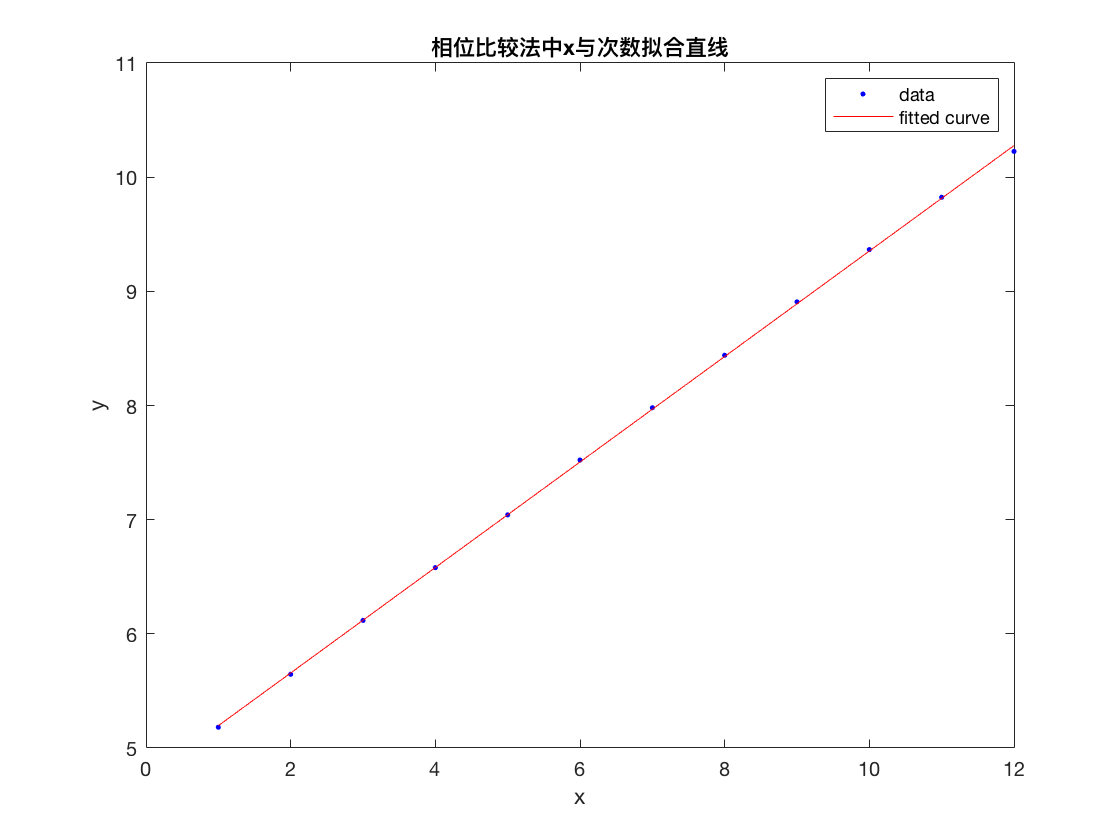

plot(fun,xx,x_xw )
title('相位比较法中x与次数拟合直线')

lamda = 2 * fun.p1

lamda =          0.923874125874126


v_b = f * lamda * 10^-2

v_b =           343.671936083916



sa = std(deltaX)

sa =         0.0199617816657912


length = size(x_gs);
ua = sa / sqrt(11-1)

ua =        0.00631246962188902


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =         0.0144445859585918


U_Lamda = 2 * Ux

U_Lamda =         0.0288891719171835



fa = std(fi)

fa =         0.0143701078632007


f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           7.18505393160033


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           58.8643625917529



U = v_b*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =            10.760234760638


va = fv(t, ps, pw, v_b)

va =           380.542079542076


% A.3 
x_wt= x_wt';
deltaX = diff(x_wt)

deltaX =                      2.576
                     2.174
                     2.148
                     2.094
                     1.942
                     1.628
                     1.736
                      2.67
                      2.27


dx_avg = mean(deltaX)

dx_avg =           2.13755555555556


% lamda = 2 * dx_avg;
ft = fittype('poly1');
xx = (1:1:10)';
fun = fit(xx, x_wt, ft)

fun =      Linear model Poly1:
     fun(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.064  (1.979, 2.149)
       p2 =      0.4836  (-0.04077, 1.008)

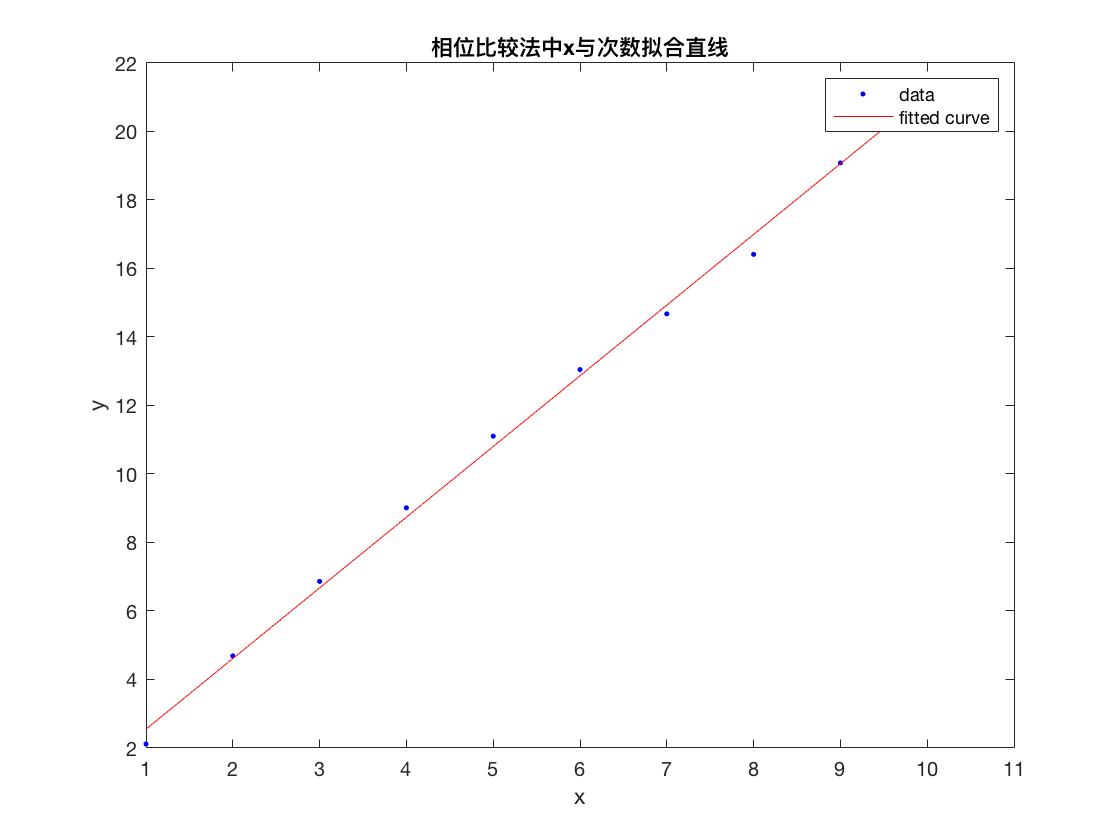

plot(fun,xx,x_wt )
title('相位比较法中x与次数拟合直线')

lamda = 2 * fun.p1

lamda =                      4.128


v_c = f * lamda * 10^-2

v_c =                 1535.57472



sa = std(deltaX)

sa =          0.345641111237911


length = size(x_gs);
ua = sa / sqrt(9-1)

ua =           0.12220258680659


Ux = sqrt((tp * ua)^2 + (kp * delta_M/C)^2)

Ux =          0.276187119278861


U_Lamda = 2 * Ux

U_Lamda =          0.552374238557722



fa = std(fi);
length = size(fi);
f_ua = fa / sqrt(5 - 1) * 1000

f_ua =           7.18505393160033


Uf = sqrt((tp*f_ua)^2 + (kp * delta_f/Cf)^2)

Uf =           58.8643625917529



U = v_c*sqrt((U_Lamda/lamda)^2 + (Uf/f)^2)

U =            205.49206027623


va = fv(t, ps, pw, v_c)

va =            1700.3157252222


% A.4
% Material 1
vvecA = l_A ./ t_A

vvecA =           1986.28571428571           2775.2808988764


v_bA = mean(vvecA)

v_bA =           2380.78330658106



vvecB = l_B ./ t_B

vvecB =           1429.01960784314          1028.73563218391


v_bB = mean(vvecB)

v_bB =           1228.87762001352
